# Future Forecast Model of Ice in the Arctic

## What Am I Researching?

This project takes certain trends of climate change that pertain to ice in the Arctic region, and looks to create a basic forecasting model to predict the amount of ice left in the Arctic when given the year. The topic of this project focuses on climate change, and its detrimental effects on an increase in ice melting, which leads to a rise in sea level and other significant issues. This project looks to combine the coding we have learned in this class with raising awareness for climate change and what it is doing to the planet.

## Why Is This Interesting AND Important?

Climate Change is arguably the most important issue facing humanity. It has been happening for years, and the planet is facing terrible and irreversible effects. Earth is being negatively affected in numerous ways. Humanity must wake up. World leaders, as well as everyday citizens, must actively work towards limiting climate change. If not, it may become too late, and the planet will be decimated. Raising awareness and providing information is one thing that many can do to help the effort.

Here, I am focusing on the increased ice melting, specifically near the North Pole. The increased temperature in the polar regions leads to an increased rate of ice melting, and even permanent ice areas becoming warm enough to begin to melt. Glaciers are getting smaller and giant ice blocks are falling into the ocean. The melting ice caps is what leads to the rising sea levels, which causes many issues.

Looking at how the Arctic changes over time can be extremely important, in both to identify trends, and to show a haunting visual of the Arctic shrinking. The physics behind it is a mix of many things but would mostly lean towards thermodynamics.

This is both interesting and important to me. It is extremely clear how significant the issue of climate change is. I am interested in searching for solutions and how we can mitigate the negative effects of it. I am a huge fan of the polar regions and cold environments, and I hate knowing that they are slowly getting smaller and losing mass and ice because of humans. I would love for this project to simply raise any form of awareness to help the cause!

**HEY, HELP SAVE THE PLANET!**

## Where Did I Start?

I wanted to create a forecast model of how the Arctic would change and look in the future based on recent trends. I was inspired by a graphic from NASA on this same topic, which showed the Arctic Ice in September from 1979 to 2020 and gave a lot of data on its ice. The data was taken in September because that is when the ice is at its minimum each year. I wanted to do a similar thing, but as a future forecasting model.

I took the raw data collected by NASA on the Arctic Ice over the past forty-one years, and went to work in MATLAB. I am looking to forecast the extent and area of the Arctic Ice in units of million square kilometers. The extent of ice is a measurement of the area of ocean where there is at least some sea ice. Usually, scientists define a threshold of minimum concentration to mark the ice edge; the most common cutoff is at 15 percent. The area of ice is a measurement of the area of ocean where there is full ice, like much of the arctic has been for centuries. 

## So.... What Does My Forecasting Model Do? 

My project consists of a collection of files and functions, but my main function is forecast. This function, which is defined in my forecast.m file, is the main piece of the project. This function allows for a future forecast of the extent and area of the Arctic Sea Ice in September to be created for a given year. Forecast also creates two visuals. The first of the two shows the world map, centered around the Arctic Sea, where the extent and area of the ice are loosely modeled over the open water. The circular models are centered at the North Pole. This was done for simplicity. Even though the models may overlap with land, I believe that for the visual, it was better to have the models centered at the North Pole rather than the exact center of the Arctic Sea. It also makes sense, as the Arctic Sea closer to the North Pole around Greenland and northern Canada is more often frozen than the other side of the Arctic Sea. The second is identical to the first, only the limits on the x and y axes are a lot smaller, which is done to see a closer view of the Arctic region.

When called with an input of a future year, this is what is created:

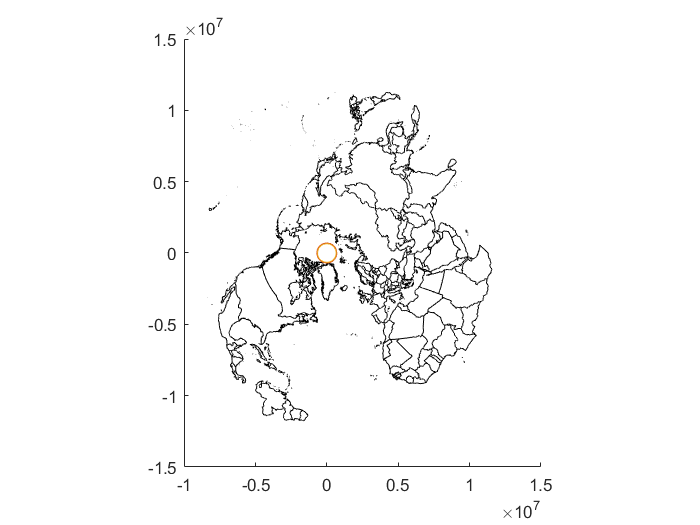

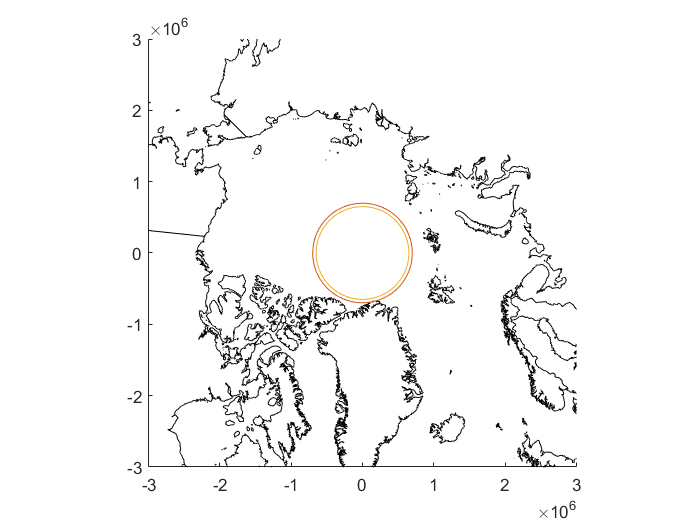

x = "The Minimum Extent of the Arctic Ice in 2100 will be 1.5293 million square km."

y = "The Minimum Area of the Arctic Ice in 2100 will be 1.3265 million square km."

clf('reset')
[x,y]=forecast(2100)

### A Deeper Dive Into Forecast

There are a few different things happening when forecast is called with a given year. It first reads the table of data taken from NASA:

IceArea = readtable("2264_N_09_extent_v3.0.xlsx","PreserveVariableNames",true);

The function then defines two figures, a larger full world view, and a smaller view centered around the Arctic.

LargerView = figure;
SmallerView = figure;

Forecast then creates two lines, one for the extent data, and one for the area data. Each line acts as a line of best fit for the extent or area as a function of the year. The two lines were created with the following code:

Ef = fit(IceArea.year,IceArea.extent,"exp1");
Af = fit(IceArea.year,IceArea.area,"exp1");

The two trend lines were created using an exponential fit. Exponential fits, along with other basic fits, are not perfect, and these are far from it. The model will never reach zero, which is *hopefully* accurate, but that could become inaccurate based on current trends. Also, near the beginning of the data at 1979, and especially before that, the estimates are much larger than the actual totals for extent and area. With the current modeling, forecast is meant to be strictly for the future, as going further into the past creates increasingly inaccurate results. This is made evident when plotted on the same axes as the actual data:

Extent = figure;
Area = figure;
Arctic = figure;
IceArea = readtable("2264_N_09_extent_v3.0.xlsx","PreserveVariableNames",true);

#### The Extent Plot

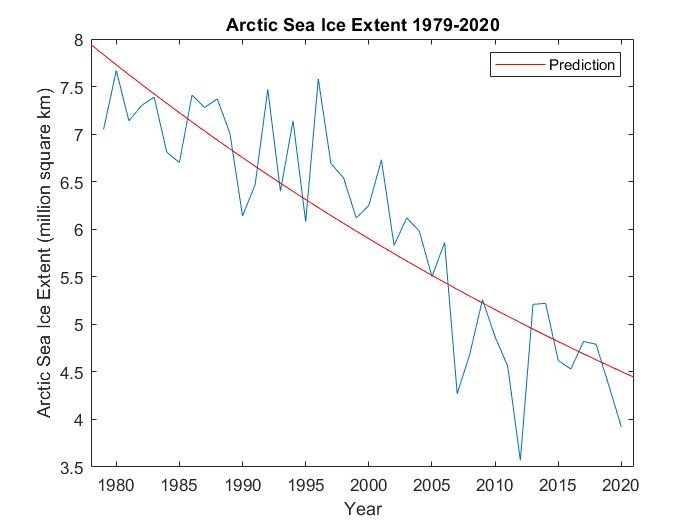

figure(Extent);
IceExtentPlot = plot(IceArea.year,IceArea.extent);
title("Arctic Sea Ice Extent 1979-2020");
xlim([1978 2021]);
hold on
ExpE = plot(fit(IceArea.year,IceArea.extent,"exp1"));
xlabel("Year");
ylabel("Arctic Sea Ice Extent (million square km)");
legend((ExpE),("Prediction"))
hold off

#### The Area Plot

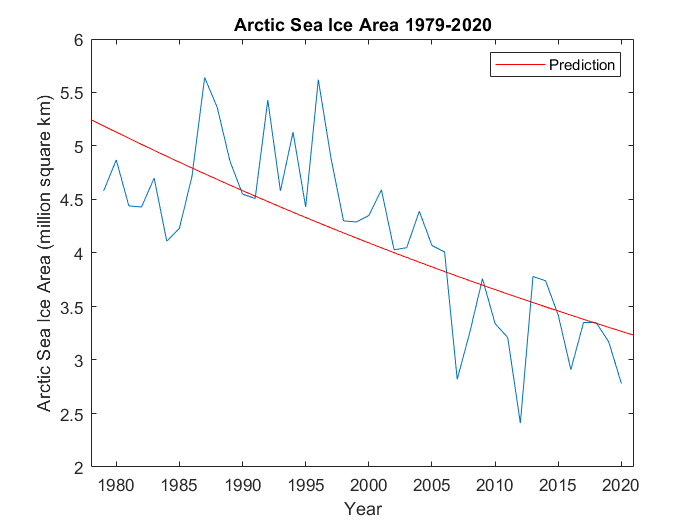

figure(Area)
IceAreaPlot = plot(IceArea.year,IceArea.area);
title("Arctic Sea Ice Area 1979-2020");
xlim([1978 2021]);
hold on
ExpA=plot(fit(IceArea.year,IceArea.area,"exp1"));
xlabel("Year");
ylabel("Arctic Sea Ice Area (million square km)");
legend((ExpA),("Prediction"))
hold off

The code to plot the data with the model was taken from my icemodel.m file, which was used as both a testing ground and a sort of playground for working with the models. As seen from the two graphs, the model could definitely use some work. However, it does function with limited accuracy.

Getting back to forecast, the function then creates two statements to output. The statements created are given in the following code, which were also shown off in the beginning demonstration of forecast.

Extent = "The Minimum Extent of the Arctic Ice in " + year + " will be " + Ef(year)+ " million square km.";
Area = "The Minimum Area of the Arctic Ice in " + year + " will be " + Af(year) + " million square km.";

These two statements are the two outputs of the function. The two visuals of the model also come with the execution of the function, but Extent and Area are the two assigned outputs. Forecast takes the value for the extent and area of the model at the value of the given year and uses those as the predicted values. The strings of text are there to clarify the units, as well as making the outputs look professional.

Although the two outputs have been finished, forecast also creates the two visuals that were shown in the beginning demonstration. The code in forecast that creates the two figures shown above is just a few lines:

figure(LargerView);
arcticborders('k-',year);
figure(SmallerView);
arcticborders('k-',year);
xlim([-3000000,3000000]);
ylim([-3000000,3000000]);

Here, the two figures that were defined at the beginning of the function are called. The larger view and smaller view figures are the same, only the smaller view figure has a limit on the x and y axes of 1.5 million in either direction. After this, the function is given an "end" to signify that it is done. With that, the syntax of forecast is complete.

### What About Arctic Borders?

One thing was clearly left out of the description of forecast. The function that was called within forecast on its last few lines is called "arcticborders" (Arctic Borders). I purposely did not explain what Arctic Borders was so that it could have its own section, because without it, I would not have the visual anywhere near where it is currently. Arctic Borders is a function within a collection of functions and files called "Arctic Mapping Tools". This collection was created by Chad A. Greene of the University of Texas at Austin Institute for Geophysics (UTIG). It was adapted from his borders function, created in May 2016. I downloaded the "Arctic Mapping Tools" collection from MATLAB File Exchange and used the Arctic Borders function.

Although the Arctic Borders function is completely credited to Chad A. Greene, I did adjust the function, which allowed to it to work in cohesion with forecast. This was necessary, as it is called within forecast, and takes an input of the year which is given when forecast is called. Arctic Borders now takes the year, along with any other inputs to change the creation of the world map, such as line color and shading. It then creates a world map centered around the Arctic Sea, with a loose circular modeling of the minimum extent and area of the Arctic Ice for the given year.

The code of Arctic Borders (with notes included) is 123 lines long, so I won't go through the code step-by-step. The link to the file exchange is available in the sources section, and the modified code will be submitted with this report. The modified code can be shared as well. However, it is important to look at the adjustments I made.

The first adjustment made to Arctic Borders was having it accept the year as an input. This was critical as it allowed for the model to be displayed on the map and could be changed based on the year. Two more outputs were also added, making it so the models for extent and area were each assigned their own output. The Arctic Borders file then parsed inputs, loaded data from a ".mat" file, and got initial conditions. Then, it was time to create the plot.

The plot section of the code was the section where the most adjustments were made. The reading of the table from NASA, along with the two exponential fits, Ef and Af, were added into the code of Arctic Borders, as they are used to create the plot. The code for these is shown on lines 3, 4, and 5 of this report. Next, hold is set on so that multiple things can be on the same figure or set of axes. The map of the world with country borders is created, with either face plots or no face plots. Face plots allow for the world map to be shaded in, while no face plots simply create borders. That code was left the same. However, added to either option (face plots or no face plots), was the two models for the extent and area. The two models are shown below:

e = circle(0,0,1000000*sqrt(Ef(year)/pi));
a = circle(0,0,1000000*sqrt(Af(year)/pi));

The two circles were created for the extent and the area, and were plotted on the world map, centered at the North Pole. Once again, the models were centered at the North Pole for a simple visual and to slightly favor the side near Greenland, rather than being centered near the middle of the Arctic Sea. Here, the extent and area were used as the area of the circles, as the circle function asked for a given radius. The circle function is another function used within Arctic Borders. Circles is a short function and is credited to Paulo Silva. I did not alter this function at all from Paulo, who provided the code on MATLAB Answers.

circle(x,y,r)
        ang=0:0.01:2*pi; 
        xp=r*cos(ang);
        yp=r*sin(ang);
        p = plot(x+xp,y+yp);

Here is an example of the circle function in action.

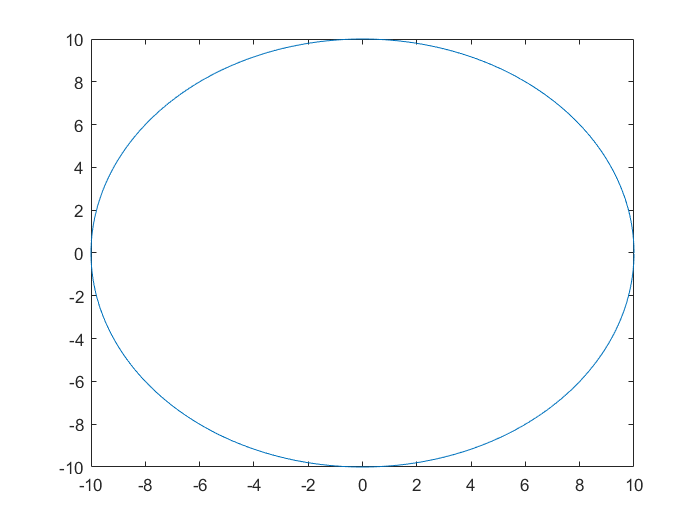

ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×629 double]
              YData: [1×629 double]
              ZData: [1×0 double]

  Show all properties


circle(0,0,10)

 The circle function in the context of the model for the extent and area estimates look like this:

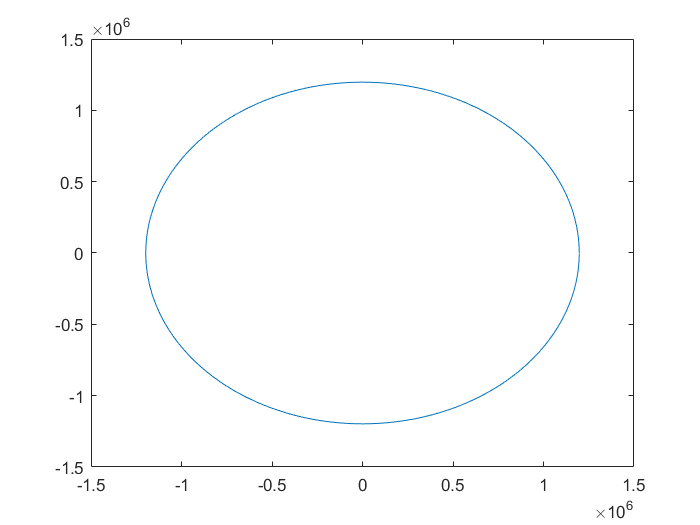

circle(0,0,1000000*sqrt(Ef(2020)/pi));
xlim([-1500000,1500000]);
ylim([-1500000,1500000]);

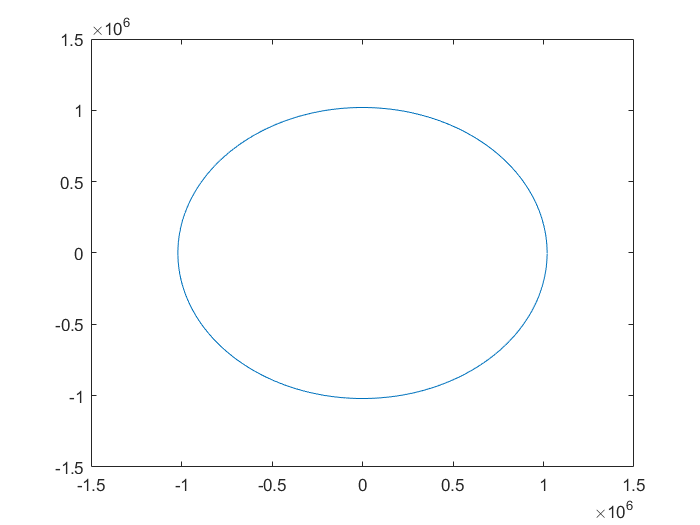

circle(0,0,1000000*sqrt(Af(2020)/pi));
xlim([-1500000,1500000]);
ylim([-1500000,1500000]);

Arctic Borders then has some code to clean things up and make sure nothing is broken before ending the function. With that, Arctic Borders is finished. The function is extremely helpful in allowing for a North Pole centered world map to be created in MATLAB. It was used within forecast with inputs of 'k-' to signify black solid lines, as well as the year provided when calling forecast.

## Let's Save the Planet (and the Ice)

With forecast and its team of other datasets, functions, and files all together, the project is complete. The topic of this project was exploring the Sea Ice in the Arctic Region. I wanted to look at trends and see how climate change was affection the North Pole and its huge supply of water. Based on data was NASA, images, and my basic model, the amount of solid water in the Arctic is decreasing, while the amount of liquid water in the Arctic is increasing. That may sound comical, but it is accurate. As the pattern concludes, the Arctic is freezing and staying frozen less and less over time. This is due to numerous factors, but the largest is climate change, and humanities indisputable contributions to it.

My future forecast model is anything but perfect; however, it gets the point across. Over time, the extent and area of the Arctic ice is decreasing. There are spikes and dips in the actual data, but the trend is still accurate. The data was taken in September, so both NASA's data and my model look worse than the average, as in September, the Arctic's Ice is at its minimum for the year. Again, this does not change the overall trend, or the implications that the trend has. Ice melting in the polar regions is one of the biggest and most dangerous effects of climate change. It can lead to habitats and entire ecosystems being changed or removed from existence, sea levels rising, and other irreversible changes.

I would love to expand on this in the future. I definitely bit off more than I could chew, as I envisioned creating a forecasting model with a visual that was on-par with NASA's, or at least looked like the Arctic Ice mass. I could sink a lot more time into creating the visual, as well as refining the model itself. As a basic model, forecast is effective. However, it is not nearly at its full potential. In the future, forecast could be modified and enhanced. This could be done with adding in other parameters, such as if humanity cut a certain percentage of carbon emissions, or if the average temperature of the Earth was rising at a much slower (or faster) pace. Also, I would eventually want to not use NASA's data for the basis of the model, but that will not be easy at all. Lastly, I would love for the model visual to look much closer to a realistic shape of the arctic ice, as a circle does not represent how different parts of the arctic would melt different. Different areas would melt differently because of the Sun, the distance to the nearest land, or other factors.

Humanity needs to step up. We need to start making significant changes, or everything will be lost. Over and over, world leaders, as well as the general public, ignore the warnings from scientists, articles, and models. Climate Change is already affecting the planet. It also is already affecting people. Coastal areas have been hurt badly in certain regions of the world. Glaciers are being melted, the average temperature of the planet is rising, the ozone layer is greatly damaged, and the sea level is rising. In a short amount of time, like 30 years, so many things may be different about Earth, and it may be too late to stop the snowball effect of Climate Change from destroying parts of the Earth. Humanity needs to work together to work towards saving the planet, as it's the only one we have. I hope my future forecast model brought any form of awareness or thought to anyone! Save the Polar Bears! Work towards saving the planet! 

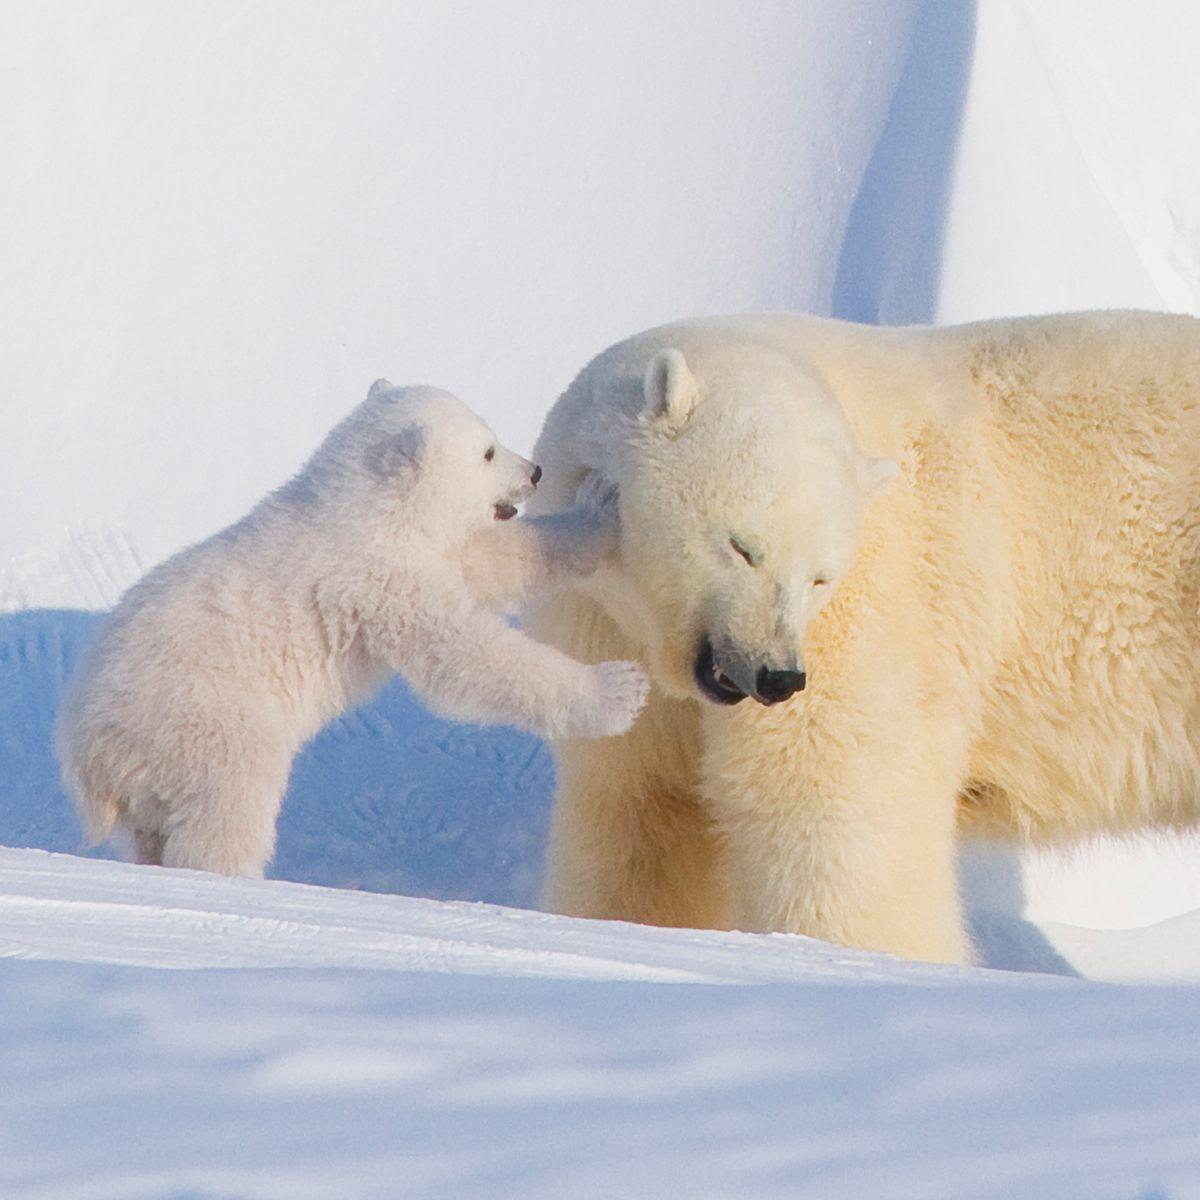

### References:

Hancock, L. (n.d.). *Six ways loss of Arctic ice impacts everyone | Pages | WWF*. World Wildlife Fund. Retrieved November 30, 2020, from https://www.worldwildlife.org/pages/six-ways-loss-of-arctic-ice-impacts-everyone#:~:text=Polar%20ice%20caps%20are%20melting

Kazlowski, S. (2020). Polar Bears. In *https://www.thecut.com/*. https://pyxis.nymag.com/v1/imgs/1be/59b/387489f1b8413ff360c3eead07c710621c-polar-bears.rsquare.w1200.jpg

MathWorks. (2020, September 16). *Add folders to search path - MATLAB addpath*. Www.Mathworks.com. https://www.mathworks.com/help/matlab/ref/addpath.html

MathWorks. (2020, September 16). *Clear current figure window - MATLAB clf*. Www.Mathworks.com. https://www.mathworks.com/help/matlab/ref/clf.html

MathWorks, & Greene, C. (2020, February 6). *Arctic Mapping Tools*. Www.Mathworks.com. https://www.mathworks.com/matlabcentral/fileexchange/63324-arctic-mapping-tools?s_tid=srchtitle

NASA. (2020). *Climate Change: Vital Signs of the Planet*. Climate Change: Vital Signs of the Planet; NASA. https://climate.nasa.gov/

NSIDC. (2012). *Quick Facts on Arctic Sea Ice | National Snow and Ice Data Center*. Nsidc.org. https://nsidc.org/cryosphere/quickfacts/seaice.html

SVS, N. (2020, October 16). *SVS: Annual Arctic Sea Ice Minimum 1979-2020 with Area Graph*. Svs.Gsfc.Nasa.Gov. https://svs.gsfc.nasa.gov/4867

Tamimi, Y., & Silva, P. (2011, March 12). *plotting circles - MATLAB Answers - MATLAB Central*. Www.Mathworks.com. https://www.mathworks.com/matlabcentral/answers/3058-plotting-circles